clear;clc;

% load parameters
par_scg = importdata('par_scg_clock.txt');
par_scg = par_scg.data;
n_E = par_scg(4);
n_I = par_scg(5);

par_clock = load('par_clock.csv');
n_clock = 12;

% initial values
y0 = zeros(n_E+n_I+n_clock+6, 1);
y0(n_clock+1) = 1;
y0(n_clock+n_I+n_E+2) = 100;
y0(n_clock+n_I+n_E+3) = 1000;

tmax = 1000;
tspan = 0:0.1:tmax;

y = zeros(length(tspan), n_E+n_I+n_clock+6, 2);
t_V_17 = 523; % from paper CT17 is the acrophase of Bmal1
t_V_6 = 512;

[~, y(:, :, 1)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y(:, :, 2)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
% par_scg(9) = 100000;
% [~, y(:, :, 5)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_0);
y = real(y);

% Effect of different tau_Es
y_tau = zeros(length(tspan), n_E+n_I+n_clock+6, 4);
par_scg(2) = 2;
[~, y_tau(:, :, 1)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y_tau(:, :, 2)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
par_scg(2) = 10;
[~, y_tau(:, :, 3)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_6);
[~, y_tau(:, :, 4)] = ode45(@ODE_SCG_CLOCK, tspan, y0, [], par_clock, par_scg, t_V_17);
y_tau = real(y_tau);

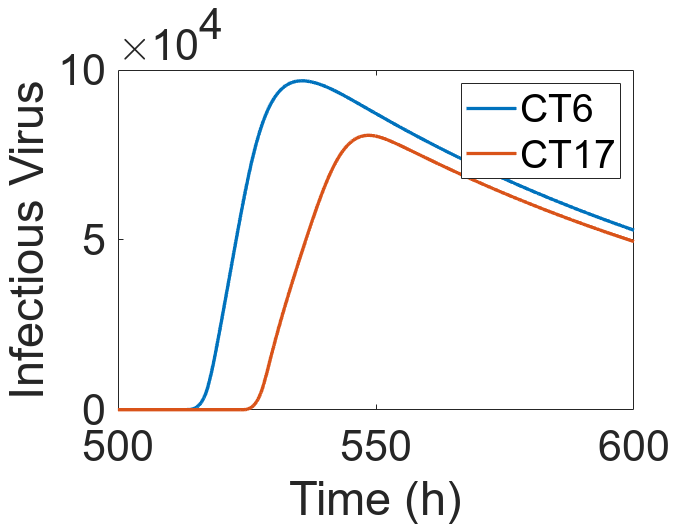

% Plot virus 
figure; hold on; set(gca,'Fontsize',26); box on;
% subplot(1, 2, 1); hold on;
for i = 1:2
    plot(tspan, y(:, n_E+n_I+n_clock+2, i), 'LineWidth', 2);
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('Infectious Virus');
legend('CT6', 'CT17');
hold off;

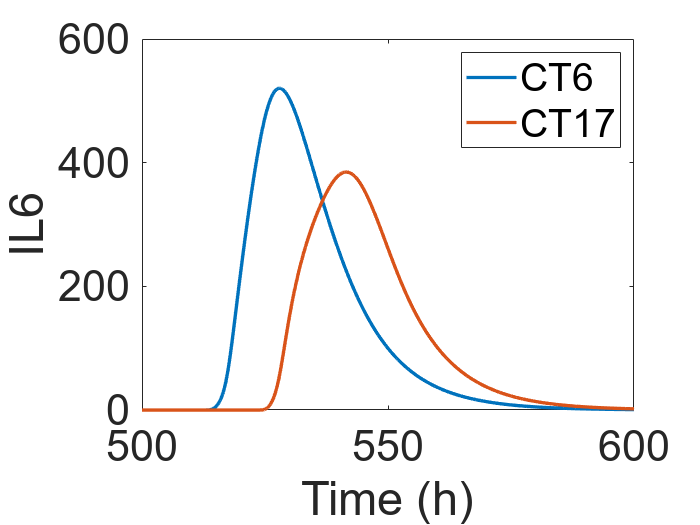


% subplot(1, 2, 2); hold on;
% for i = 1:2
%     plot(tspan, y(:, n_E+n_I+n_clock+3, i));
% end
% xlim([500 600]);
% xlabel('Time (h)'); ylabel('Total Virus');
% legend('CT6', 'CT17');
% hold off;

% Plot cytokines
figure; hold on; set(gca,'Fontsize',26); box on;
% subplot(1, 3, 1); hold on;
for i = 1:2
    plot(tspan, y(:, n_E+n_I+n_clock+4, i), 'LineWidth', 2);
end
xlim([500 600]);
xlabel('Time (h)'); ylabel('IL6');
legend('CT6', 'CT17');
hold off;

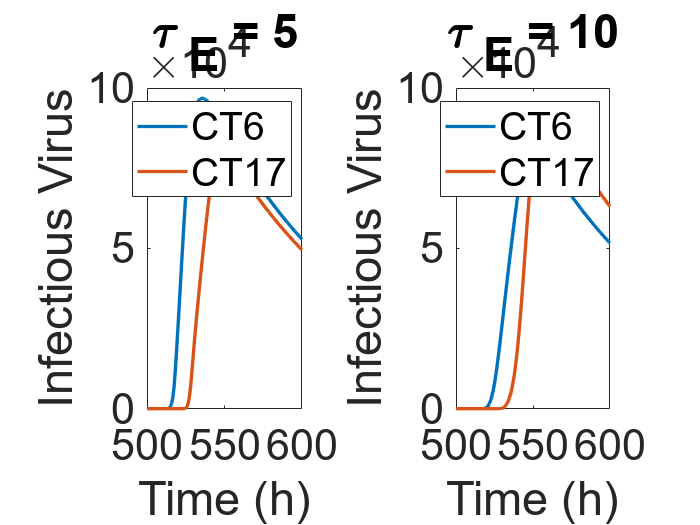


% subplot(1, 3, 2); hold on;
% for i = 1:2
%     plot(tspan, y(:, n_E+n_I+n_clock+5, i));
% end
% xlim([500 600]);
% xlabel('Time (h)'); ylabel('IL1b');
% % legend('CT0', 'CT6', 'CT12', 'CT18', 'Bmal1 KO');
% hold off;
% 
% subplot(1, 3, 3); hold on;
% for i = 1:2
%     plot(tspan, y(:, n_E+n_I+n_clock+6, i));
% end
% xlim([500 600]);
% xlabel('Time (h)'); ylabel('IL10');
% legend('CT6', 'CT17');
% hold off;

% different tau_E
figure;
subplot(1, 2, 1); hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y_tau(:, n_E+n_I+n_clock+2, 1), 'LineWidth', 2);
plot(tspan, y_tau(:, n_E+n_I+n_clock+2, 2), 'LineWidth', 2);
xlim([500 600]);
xlabel('Time (h)'); ylabel('Infectious Virus'); title('\tau _E = 5');
legend('CT6', 'CT17');
hold off;

subplot(1, 2, 2); hold on; set(gca,'Fontsize',26); box on;
plot(tspan, y_tau(:, n_E+n_I+n_clock+2, 3), 'LineWidth', 2);
plot(tspan, y_tau(:, n_E+n_I+n_clock+2, 4), 'LineWidth', 2);
xlim([500 600]);
xlabel('Time (h)'); ylabel('Infectious Virus'); title('\tau _E = 10');
legend('CT6', 'CT17');
hold off;